load doc\pomiary\lab_1\drgania_skok_jednostkowy.mat
load doc\pomiary\lab2\pomiary_silnika.mat

Pomiary charakterystyki silnika do zmierzenia jego dynamiki:

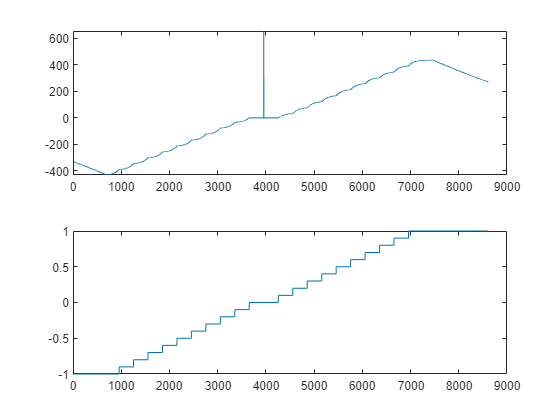

dodatnie_rpm = pomiar_charakterystyki_silnika_dodatni.signals(5).values;
ujemne_rpm = flip(pomiar_charakterystyki_silnika_ujemna.signals(5).values);
dodatnie_ctrl = pomiar_charakterystyki_silnika_dodatni.signals(7).values;
ujemne_ctrl = flip(pomiar_charakterystyki_silnika_ujemna.signals(7).values);
rpm = [ujemne_rpm; dodatnie_rpm];
ctrl = [ujemne_ctrl; dodatnie_ctrl];
figure
subplot(2, 1, 1)
plot(rpm)
subplot(2, 1, 2)
plot(ctrl)

Równanie silnika ma postać:

Pomiary obrotów w stanie ustalonym:

rpm_ss = [-429, -388, -347, -299, -259, -213, -166, -123, -77, -32, 0, 33, 76, 120, 169, 213, 261, 303, 345, 397, 436];
u_ss = -1:0.1:1;
p = polyfit(rpm_ss, u_ss, 4)

p =    -0.0000   -0.0000   -0.0000    0.0024    0.0004


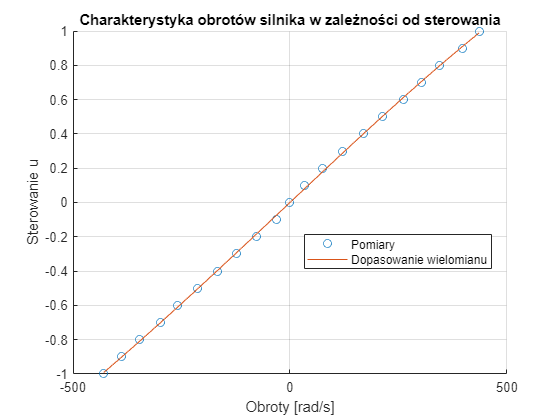

u_from_poly = polyval(p, rpm_ss);
figure
hold on
plot(rpm_ss, u_ss, 'o')
plot(rpm_ss, u_from_poly)
grid on
legend('Pomiary', 'Dopasowanie wielomianu', Location='best')
title('Charakterystyka obrotów silnika w zależności od sterowania')
xlabel('Obroty [rad/s]')
ylabel('Sterowanie u')
hold off

Dane wykorzystane do estymacji współczynnika G:

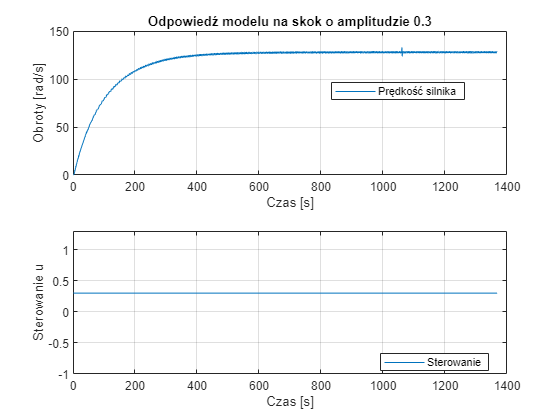

silnik_rpm_1 = drgania_skok_jednostkowy_0_3.signals(5).values;
control_1 = drgania_skok_jednostkowy_0_3.signals(7).values;
current_1 = drgania_skok_jednostkowy_0_3.signals(6).values;
figure
subplot(2, 1, 1)
plot(silnik_rpm_1)
grid on
legend('Prędkość silnika', Location='best')
title('Odpowiedź modelu na skok o amplitudzie 0.3')
ylabel('Obroty [rad/s]')
xlabel('Czas [s]')
subplot(2, 1, 2)
plot(control_1)
grid on
legend('Sterowanie', Location='best')
ylabel('Sterowanie u')
xlabel('Czas [s]')

G = 420.7;

Przeprowadzenie symulacji i walidacji danych:

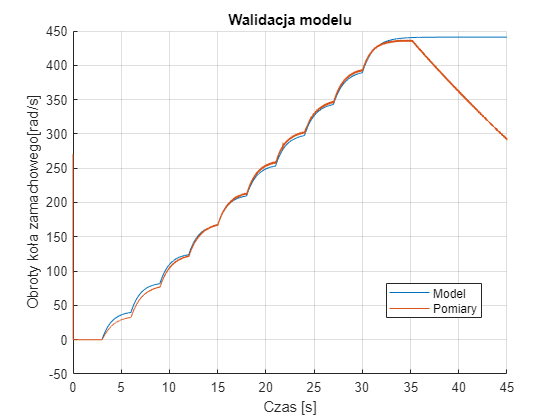

validation_data = out.Engine_validation_rpm.signals(1).values(1:4500);
test_data = out.Engine_validation_rpm.signals(2).values(1:4500);
figure
hold on
plot(out.Engine_validation_rpm.time(1:4500), validation_data);
plot(out.Engine_validation_rpm.time(1:4500), test_data);
grid on
legend('Model', 'Pomiary', Location='best')
title('Walidacja modelu')
xlabel('Czas [s]')
ylabel('Obroty koła zamachowego[rad/s]')
hold off